# Show Productive Structure Demo

Show the Productive Structure Info and the Productive Diagrams.

### Read Data Model

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data=ReadDataModel(file);

### Get the Productive Structure Tables

res=ProductiveStructure(data,'Show',true);


Flows Definition Table - SUMMARY

  Id Key  From     To       Type      
———————————————————————————————————————
   1 NG   ENV_R1   COMB_F1  RESOURCE  
   2 B1   ENV_R2   CMP_P1   RESOURCE  
   3 B2   CMP_P1   APH_P1   INTERNAL  
   4 B3   APH_P1   COMB_F1  INTERNAL  
   5 B4   COMB_P1  TRB_F1   INTERNAL  
   6 B5   TRB_F1   APH_F1   INTERNAL  
   7 B6   APH_F1   HRSG_F1  INTERNAL  
   8 B7   HRSG_F1  STCK_F1  INTERNAL  
   9 WC   TRB_P1   CMP_F1   INTERNAL  
  10 WN   TRB_P1   ENV_O1   OUTPUT    
  11 QV   HRSG_P1  ENV_O2   OUTPUT    
  12 QG   STCK_P1  ENV_W1   WASTE     


Productive Groups Definition Table - SUMMARY

  Id Key      Definition  Type      
—————————————————————————————————————
   1 COMB_F1  NG+B3       FUEL      
   2 COMB_P1  B4          PRODUCT   
   3 CMP_F1   WC          FUEL      
   4 CMP_P1   B2-B1       PRODUCT   
   5 TRB_F1   B4-B5       FUEL      
   6 TRB_P1   WC+WN       PRODUCT   
   7 APH_F1   B5-B6       FUEL      
   8 APH_P1   B3-B2       PRODUCT   

### Save Diagrams

Get the the productive diagrams by means of `ProductiveDiagram` function, use the option `SaveAs `to save in excel format the adjacency tables, and shows the Flows Diagram (fat) using the `ShowGraph` function

dg=ProductiveDiagram(data,'SaveAs','diagrams.xlsx');

INFO: cMessageLogger. Productive Diagram is saved in file diagrams.xlsx


### Plot Diagrams

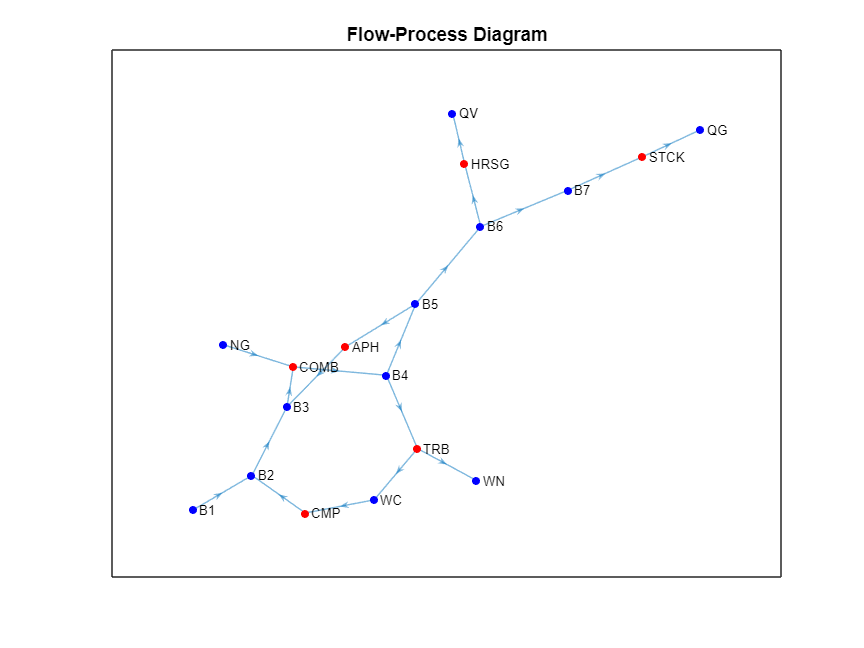

ShowGraph(dg,'Graph',cType.Tables.FLOW_PROCESS_DIAGRAM);

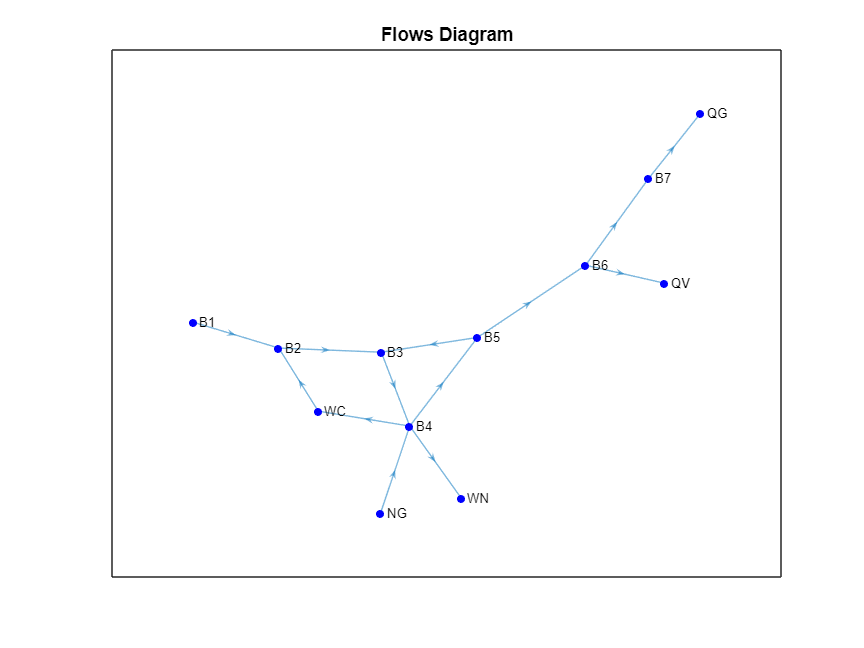

ShowGraph(dg,'Graph',cType.Tables.FLOW_DIAGRAM); 

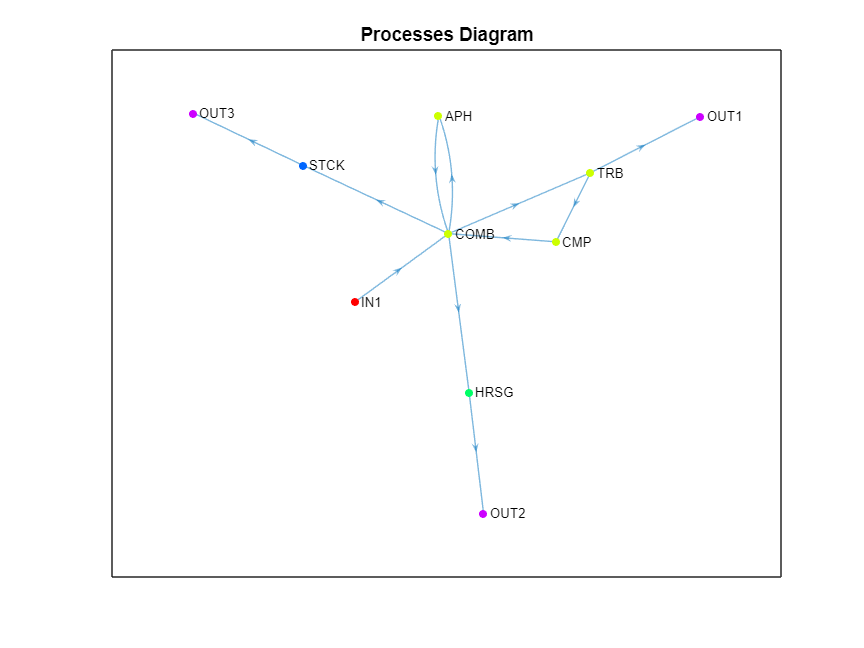

ShowGraph(dg,'Graph',cType.Tables.PROCESS_DIAGRAM)

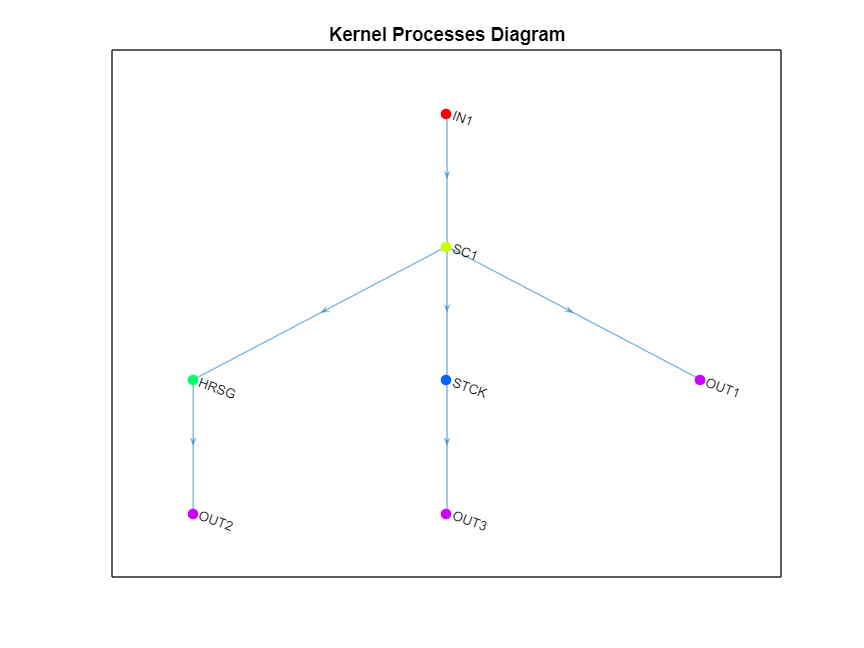

ShowGraph(dg,'Graph',cType.Tables.KPROCESS_DIAGRAM);

ShowResults(res,'Table',cType.Tables.PROCESS_TABLE);


Processes Definition Table - SUMMARY

  Id Key   Fuel   Product  Group  Type         
————————————————————————————————————————————————
   1 COMB  NG+B3  B4       SC1    PRODUCTIVE   
   2 CMP   WC     B2-B1    SC1    PRODUCTIVE   
   3 TRB   B4-B5  WC+WN    SC1    PRODUCTIVE   
   4 APH   B5-B6  B3-B2    SC1    PRODUCTIVE   
   5 HRSG  B6-B7  QV       HRSG   PRODUCTIVE   
   6 STCK  B7     QG       STCK   DISSIPATIVE  



### Additional Help Information

help ProductiveStructure

 ProductiveStructure - Get the productive structure of the plant.
    If 'Show' option is activated it displays the productive structure tables on the console.
    If 'SaveAs' option is used these tables are saved in an external file.
 
    Syntax
      res = ProductiveStructure(data,Name,Value)
 
    Input Arguments
      data - cReadModel object containing the data information
     
    Name-Value Arguments
      Show -  Show the results on console.  
        true | false (default)
      SaveAs - Name of file (with extension) to save the results.
        char array | string
 
    Output Arguments
      res - cResultsInfo object contains the productive structure information
      The following tables are obtained:
        flows - Flows definition table
        streams - Streams definition table
        processes - Processes definition table
 
    Example
      Productive Structure Demo
 
    See al

help ProductiveDiagram

 ProductiveDiagram - Get the productive diagrams of the plant.
    These diagrams could be represented graphically using the function
    ShowGraph, or saving the adjacency tables in xlsx format, which can be
    used by external graph software such as yEd
 
    Syntax
      res = ProductiveDiagram(data,Name,Value)
 
    Input Arguments
      data - cReadModel object containing the data information
     
    Name-Value Arguments
      Show -  Show the results on console.  
        true | false (default)
      SaveAs - Name of file (with extension) to save the results.
        char array | string
 
    Output Arguments
      res - cResultsInfo object contains the productive structure information
      The following tables are obtained:
        sfpat - Productive (Stream-Flow-Process) adjacency table
        fpat  - Flow-Process adjacency table
        fat   - Flow adjacency table
        pat   - Process adjacency table
        kpat  - Kernel adjacency t